**Clock Simulation Program**

- **Background**

A clock is modelled as obeying the following stochastic differential equation (L. Galleani et al 2003).


$$\mathbf{dW}=(\mathbf{F}\mathbf{X}+\mathbf{M})dt+\mathbf{Q}\mathbf{dW}$$


where $\mathbf{X}=(x(t),y(t),w(t))$ 

$x(t)$ is the time deviation from true time.

$y(t)$ is the frequency deviation from the standard frequency.

$w(t)$ is the frequency drift.

$\mathbf{M}=(\mu_1,\mu_2,\mu_3)$ is an additional drift and $\mathbf{dW}=\xi(t) dt$ where $\xi(t) \sim N(0,1)$

$\mathbf{F}=\pmatrix{0 & 1 & 0 \cr 0 & 0 & 1 \cr 0 & 0 & 0}$ and $\mathbf{Q}=\pmatrix{\sigma_1 & 0 & 0 \cr 0 & \sigma_2 & 0 \cr 0 & 0 & \sigma_3}$.

Given that the expression is linear, the solution in closed form is


$$\mathbf{X}(t)=\mathbf{\Phi}_{t,0}\mathbf{X}(t_0)+\mathbf{B}_t\mathbf{M}+\mathbf{G}_t$$


where $\Phi_{t-s}=e^{(t-s) \mathbf{F}} = \pmatrix{1 & (t-s) & \frac{1}{2}(t-s)^2 \cr 0 & 1 & (t-s) \cr 0 & 0 & 1}$, $\mathbf{B}_t=\pmatrix{t & \frac{1}{2}t^2 & \frac{1}{6}t^3 \cr 0 & t & \frac{1}{2}t^2 \cr 0 & 0 & t}$ and $\mathbf{G}_t \sim N(\mathbf{0},\mathbf{\Sigma_t})$ where $\mathbf{\Sigma_t}=\pmatrix{\sigma_1^2t+\sigma_2^2\frac{t^3}{3}+\sigma_3^2 \frac{t^5}{20} & \sigma_2^2 \frac{t^2}{2}+\sigma_3^2 \frac{t^4}{8} & \sigma_3^2 \frac{t^3}{6} \cr \sigma_2^2 \frac{t^2}{2}+\sigma_3^2 \frac{t^4}{8} & \sigma_2^2t+\sigma_3^2 \frac{t^3}{3} & \sigma_3^2 \frac{t^2}{2} \cr \sigma_3^2 \frac{t^3}{6} & \sigma_3^2 \frac{t^2}{2} & \sigma_3^2t}$ 

(C. Zucca & P. Tavella 2005).

The discretization of the differential equation with equally spaced time intervals $0=t_1<t_2<...<t_{n+1}=T$ where $\tau=t_{k+1}-t_k$ is the system


$$x_i=x_{i-1}+\tau y_{i-1}+ \frac{\tau^2}{2} w_{i-1}+\mu_3 \frac{\tau^3}{6}+\epsilon_1\\
y_i=y_{i-1}+\tau w_{i-1}+\mu_3 \frac{\tau^2}{2}+\epsilon_2\\
w_i=w_{i-1}+\mu_3 \tau+\epsilon_3$$$


under the assumption $\mu_1=\mu_2=0$.

The noise is defined as $(\epsilon_1,\epsilon_2,\epsilon_3) \sim N(\mathbf{0},\mathbf{Q})$ where $\mathbf{Q}=\pmatrix{\sigma_1^2\tau+\sigma_2^2\frac{\tau^3}{3}+\sigma_3^2 \frac{\tau^5}{20} & \sigma_2^2 \frac{\tau^2}{2}+\sigma_3^2 \frac{\tau^4}{8} & \sigma_3^2 \frac{\tau^3}{6} \cr \sigma_2^2 \frac{\tau^2}{2}+\sigma_3^2 \frac{\tau^4}{8} & \sigma_2^2\tau+\sigma_3^2 \frac{\tau^3}{3} & \sigma_3^2 \frac{\tau^2}{2} \cr \sigma_3^2 \frac{\tau^3}{6} & \sigma_3^2 \frac{\tau^2}{2} & \sigma_3^2\tau}$ is the covariant matrix.

(R. Jones & V. Tryon 1983)

Refer to *Clock_Simulator.m* which computes the numerical integration for $(x(t),y(t),w(t))$.

There exists a relationship between the diffusion coefficients $(\sigma_1,\sigma_2,\sigma_3)$ and the Allen variance of a clock $\sigma_y^2(\tau)$ described by


$$\sigma_y^2
(\tau)=\frac{\sigma_1^2}{\tau}+\frac{\sigma_2^2}{3}\tau+\frac{\tau^2}{2}c_3$$


under the assumption $\sigma_3=0$ and $w(t)=c_3$ is a constant.

(C. Zucca & P. Tavella 2005).

Refer to *Diffusion_Coefficient_Estimator *which uses the expression to estimate diffusion coefficient values.

**Modelling Clocks**

Lets assume $\mu_3=0$ (the term of the frequency drift of a given clock linear in time is negligible).

The clocks we shall evaluate are

- Caesium Atomic Clock: NPL Caesium Fountain.

- Rubidium Atomic Clocks: GNSS Clock.

- Optical Atomic Clocks: Optical Lattic Clock from PTB.

- CSAC: SA45.m CSAC devloped by microsemi.

(B. L. Schmittberger & D. R. Scherer 2020)

The key distinctions between the clocks we will be modelling is their frequency drift $w(t)$ (assume constant) and the Allan variance $\sigma_y^2(\tau)$.

**Caesium Atomic Clocks:**

Microwave atomic clocks generally have an uncertainty of magnitude $10^{-13}$- $10^{-16}$

Examples:

- NIST-F1: $3 \times 10^{-16}$ (NIST 2010)

- Commercial MuClock, Muquans: $10^{-14}$ (Muquans 2019)

- ACE/PHARO space mission: $1.4 \times 10^{-15}$ (P. Laurent et al 2015)

The time deviaion is of order $10^{-10}$ - $10^{-11}$ seconds per day.

Running the *Clock_Simulator.m *simulation produces the following results

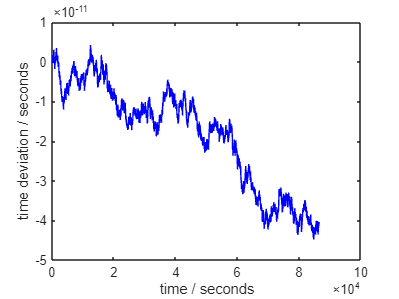

clear

% # intervals evaluted (can be any number, required to be large).

n=86400;

% Size of time interval (can be any number, required to be small wrt n).

d=1; % time interval is in unit seconds.

% Initial values.
% X_0(3) should be a known frequency drift of the clock being simulated.

X_0=[0,0,10^-22]; % frequency drift is in unit seconds^-1.

% Generate estimates for diffusion coefficients (assume frequency drift is
% constant).

diff=Diffusion_Coefficient_Estimator((1*10^-13)^2,(1*10^-15)^2,1,10^5,0); % Allen variance is in unit seconds^-1.

% assuming mu=0

mu=[0,0,0];

% Plot time deviation.

N=1:n+1;
[x,~,~]=Clock_Simulator(n,d,X_0,diff, mu);
plot(N,x,'b')

%axis([0 n -10^-9 10^-9])
xlabel('time / seconds')
ylabel('time deviation / seconds')

We may want to consider the average deviation per day from true time. As the gaussian random walk has mean zero, the distribution of the time deviations in a given interval is normally distributed. Below is a histogram annd a fitted normal for the time deviation distribution over 6 hours (using 100 iterations),

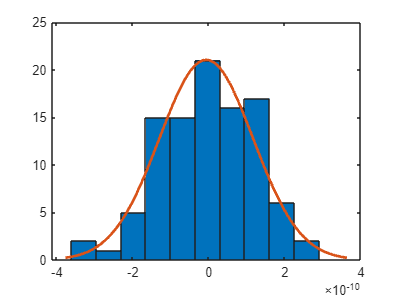

clear

% # intervals evaluted (can be any number, required to be large).

n=21600; %% over 6 hours

% Size of time interval (can be any number, required to be small wrt n).

d=1; % time interval is in unit seconds.

% Initial values.
% X_0(3) should be a known frequency drift of the clock being simulated.

X_0=[0,0,10^-22]; % frequency drift is in unit seconds^-1.

% Generate estimates for diffusion coefficients (assume frequency drift is
% constant).

diff=Diffusion_Coefficient_Estimator((8*10^-13)^2,(9*10^-16)^2,1,10^6,0); % Allen variance is in unit seconds^-1.

% assuming mu=0

mu=[0,0,0];

% Plot histogram of time deviation.

N=100;
time_dev=zeros(1,N);
max_time_dev=zeros(1,N);

for i=1:N
    [x,~,~]=Clock_Simulator(n,d,X_0,diff, mu);
    time_dev(i)=x(end);
    max_time_dev(i)=max(abs(x));
end

histfit(time_dev)

Given the offsets after 6 hour, we can consider a folded normal to find the average absolute deviation of the time offsets and the standard deviation. We may also want to consider how the maximum deviation from true time behaves.

% mean, std for absolute deviation.

mean(abs(time_dev))

ans = 9.9526e-11

std(abs(time_dev))

ans = 7.2379e-11


%mean, std for maximum deviation.

mean(max_time_dev)

ans = 1.4860e-10

std(max_time_dev)

ans = 6.1344e-11

**Rubidium Atomic Clocks**

Time-deviation within a day should be the same order of magnitude as a caesium clock. However, in general Rubidium clocks are slightly worse than the caesium clocks used to keep UTC.

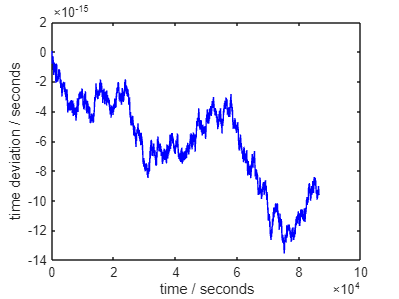

clear

% # intervals evaluted (can be any number, required to be large).

n=86400;

% Size of time interval (can be any number, required to be small wrt n).

d=1; % time interval is in unit seconds.

% Initial values.
% X_0(3) should be a known frequency drift of the clock being simulated.

X_0=[0,0,10^-19]; % frequency drift is in unit seconds^-1.

% Generate estimates for diffusion coefficients (assume frequency drift is
% constant).

diff=Diffusion_Coefficient_Estimator((5*10^-12)^2,(1.5*10^-14)^2,1,10^5,0); % Allen variance is in unit seconds^-1.

% assuming mu=0

mu=[0,0,0];

% Plot time deviation.

N=1:n+1;
[x,~,~]=Clock_Simulator(n,d,X_0,diff, mu);
plot(N,x,'b')

%axis([0 n -10^-9 10^-9])
xlabel('time / seconds')
ylabel('time deviation / seconds')

Calculating the absolute deviation and maximum deviation,

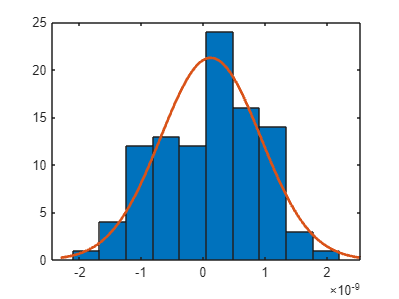

clear

% # intervals evaluted (can be any number, required to be large).

n=21600; %% over 6 hours

% Size of time interval (can be any number, required to be small wrt n).

d=1; % time interval is in unit seconds.

% Initial values.
% X_0(3) should be a known frequency drift of the clock being simulated.

X_0=[0,0,10^-19]; % frequency drift is in unit seconds^-1.

% Generate estimates for diffusion coefficients (assume frequency drift is
% constant).

diff=Diffusion_Coefficient_Estimator((5*10^-12)^2,(1.5*10^-14)^2,1,10^5,0); % Allen variance is in unit seconds^-1.

% assuming mu=0

mu=[0,0,0];

% Plot histogram of time deviation.

N=100;
time_dev=zeros(1,N);

for i=1:N
    [x,~,~]=Clock_Simulator(n,d,X_0,diff, mu);
    time_dev(i)=x(end);
    max_time_dev(i)=max(abs(x));
end

histfit(time_dev)


% mean, std for absolute deviation.

mean(abs(time_dev))

ans = 6.8090e-10

std(abs(time_dev))

ans = 4.4455e-10


%mean, std for maximum deviation.

mean(max_time_dev)

ans = 9.7490e-10

std(max_time_dev)

ans = 3.8218e-10

**Chip-Sized Atomic Clocks**

The time deviation in a day for CSAC is a few microseconds.

Running the *Clock_Simulator.m *simulation produces the following results

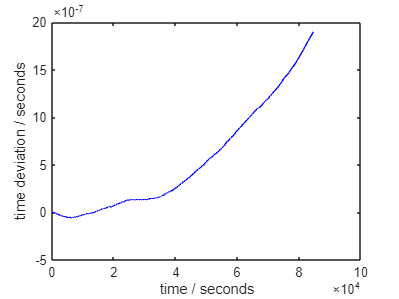

clear

% # intervals evaluted (can be any number, required to be large).

n=84600;

% Size of time interval (can be any number, required to be small wrt n).

d=1; % time interval is in unit seconds.

% Initial values.
% X_0(3) should be a known frequency drift of the clock being simulated.

X_0=[0,0,4*10^-16]; % frequency drift is in unit seconds^-1.

% Generate estimates for diffusion coefficients (assume frequency drift is
% constant).

diff=Diffusion_Coefficient_Estimator((10^-10)^2,(10^-12)^2,1,10^3,0); % Allen variance is in unit seconds^-1.

% assuming mu=0

mu=[0,0,0];

% Plot time deviation.

N=1:n+1;
[x,~,~]=Clock_Simulator(n,d,X_0,diff, mu);
plot(N,x,'b')

%axis([0 n -10^-5 10^-5])
xlabel('time / seconds')
ylabel('time deviation / seconds')

Calculating the absolute deviation and maximum deviation,

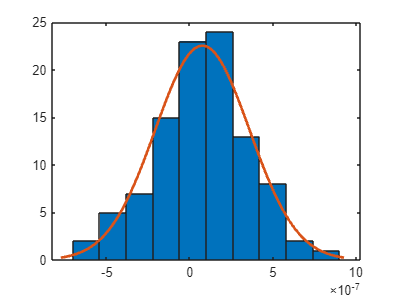

clear

% # intervals evaluted (can be any number, required to be large).

n=21600; %% over 6 hours

% Size of time interval (can be any number, required to be small wrt n).

d=1; % time interval is in unit seconds.

% Initial values.
% X_0(3) should be a known frequency drift of the clock being simulated.

X_0=[0,0,4*10^-16]; % frequency drift is in unit seconds^-1.

% Generate estimates for diffusion coefficients (assume frequency drift is
% constant).

diff=Diffusion_Coefficient_Estimator((10^-10)^2,(10^-12)^2,1,10^3,0); % Allen variance is in unit seconds^-1.

% assuming mu=0

mu=[0,0,0];

% Plot histogram of time deviation.

N=100;
time_dev=zeros(1,N);

for i=1:N
    [x,~,~]=Clock_Simulator(n,d,X_0,diff, mu);
    time_dev(i)=x(end);
    max_time_dev(i)=max(abs(x));
end

histfit(time_dev)


% mean, std for absolute deviation.

mean(abs(time_dev))

ans = 2.3062e-07

std(abs(time_dev))

ans = 1.7982e-07


%mean, std for maximum deviation.

mean(max_time_dev)

ans = 2.3832e-07

std(max_time_dev)

ans = 1.7358e-07

**Optical Clocks**

The time deviation in a day for CSAC is a of an order $10^{-13}$ seconds.

Running the *Clock_Simulator.m *simulation produces the following results

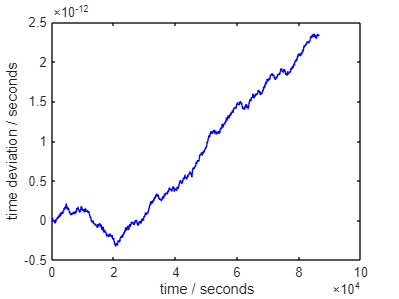

clear

% # intervals evaluted (can be any number, required to be large).

n=86400;

% Size of time interval (can be any number, required to be small wrt n).

d=1; % time interval is in unit seconds.

% Initial values.
% X_0(3) should be a known frequency drift of the clock being simulated.

X_0=[0,0,3.8*10^-23]; % frequency drift is in unit seconds^-1.

% Generate estimates for diffusion coefficients (assume frequency drift is
% constant).

diff=Diffusion_Coefficient_Estimator((7.5*10^-16)^2,(2.9*10^-17)^2,3,2*10^5,0); % Allen variance is in unit seconds^-1.

% assuming mu=0

mu=[0,0,0];

% Plot time deviation.

N=1:n+1;
[x,~,~]=Clock_Simulator(n,d,X_0,diff, mu);
plot(N,x,'b')

%axis([0 n -10^-5 10^-5])
xlabel('time / seconds')
ylabel('time deviation / seconds')

Calculating the absolute deviation and maximum deviation,

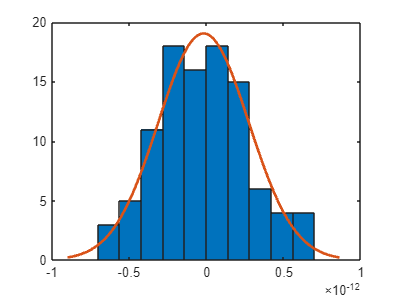

clear

% # intervals evaluted (can be any number, required to be large).

n=21600; %% over 6 hours

% Size of time interval (can be any number, required to be small wrt n).

d=1; % time interval is in unit seconds.

% Initial values.
% X_0(3) should be a known frequency drift of the clock being simulated.

X_0=[0,0,3.8*10^-23]; % frequency drift is in unit seconds^-1.

% Generate estimates for diffusion coefficients (assume frequency drift is
% constant).

diff=Diffusion_Coefficient_Estimator((7.5*10^-16)^2,(2.9*10^-17)^2,3,2*10^5,0); % Allen variance is in unit seconds^-1.

% assuming mu=0

mu=[0,0,0];

% Plot histogram of time deviation.

N=100;
time_dev=zeros(1,N);

for i=1:N
    [x,~,~]=Clock_Simulator(n,d,X_0,diff, mu);
    time_dev(i)=x(end);
    max_time_dev(i)=max(abs(x));
end

histfit(time_dev)


% mean, std for absolute deviation.

mean(abs(time_dev))

ans = 2.3672e-13

std(abs(time_dev))

ans = 1.7263e-13


%mean, std for maximum deviation.

mean(max_time_dev)

ans = 3.0113e-13

std(max_time_dev)

ans = 1.4805e-13

**VCXO Clocks**

The time deviation in a day for CSAC is a of an order $10^{-3}$ seconds.

Running the *Clock_Simulator.m *simulation produces the following results

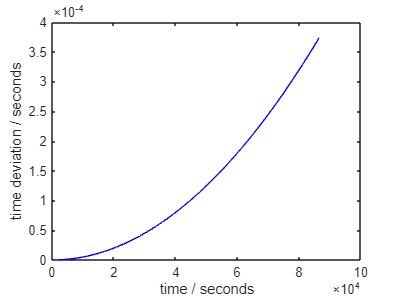

clear

% # intervals evaluted (can be any number, required to be large).

n=86400;

% Size of time interval (can be any number, required to be small wrt n).

d=1; % time interval is in unit seconds.

% Initial values.
% X_0(3) should be a known frequency drift of the clock being simulated.

X_0=[0,0,10^-13]; % frequency drift is in unit seconds^-1.

% Generate estimates for diffusion coefficients (assume frequency drift is
% constant).

diff=Diffusion_Coefficient_Estimator((5*10^-11)^2,(10^-12)^2,1,10^3,0); % Allen variance is in unit seconds^-1.

% assuming mu=0

mu=[0,0,0];

% Plot time deviation.

N=1:n+1;
[x,~,~]=Clock_Simulator(n,d,X_0,diff, mu);
plot(N,x,'b')

%axis([0 n -10^-5 10^-5])
xlabel('time / seconds')
ylabel('time deviation / seconds')

**Analysis**

From the above analysis of each simulated clock the following is reproduced (in the time iterval of 6 hours).

The following figures demonstrates the variability of the time deviations over a day for each clock model.

- Atomic Clock

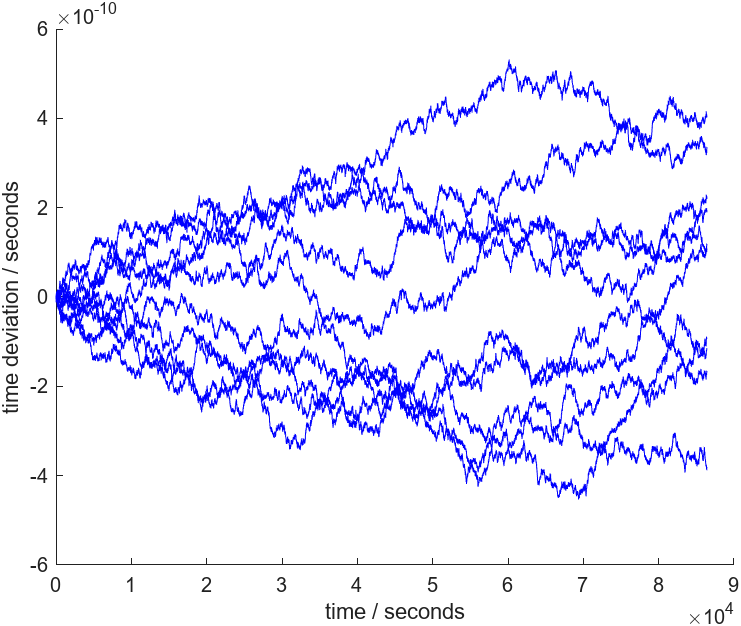

- CSAC

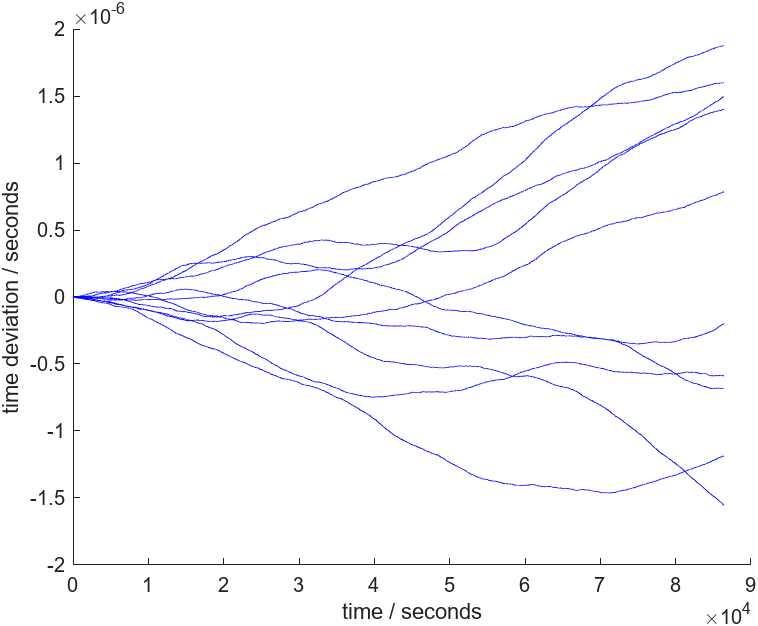

- Optical

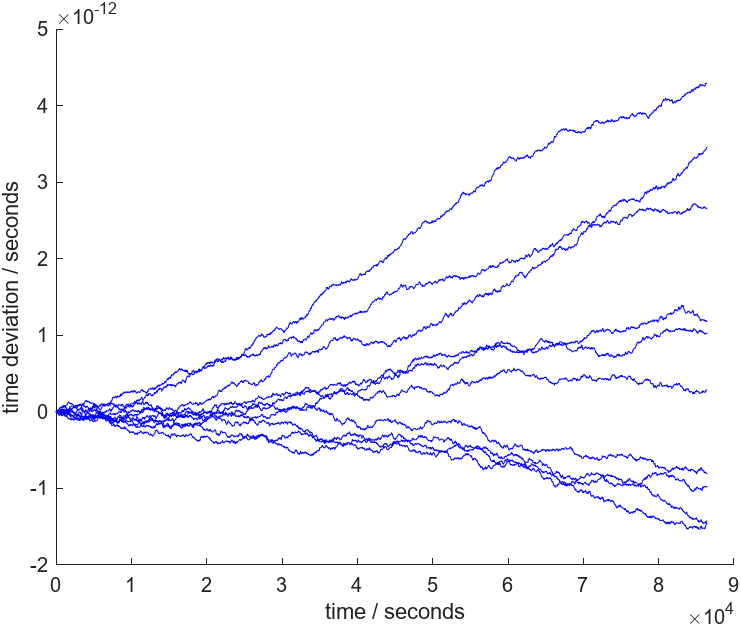

A basic analysis of the results indicates that Optical clocks have the best timing with a time offest within a few parts in $10^{-12}$ seconds. CSAC has the best stability (reduced bumpiness) within its respective timescale but the frequency drift means that CSAC clocks accumulate a larger time offset of a couple microseconds. Atomic clocks has a smaller offset within a few parts in $10^{-10}$ than CSAC but lack in stability wiithin its respective timescale.

The following is a log-log comparison of each clock and the results are what we would expect.